clear all
%% Contour points (oriented correctly) and mesh size parameters
Lx = 60e-3;
Lx_outer = 20e-3;
Ly = 45e-3;
rAperture1 = 3e-3;
rAperture2 = 1.5e-3;
rAperture3 = 1e-3;
d = 34e-3;
Lx_outer2 = 120e-3;


isAxisymmetric = 1;


N_field = 6;
N_geom = 2;
N_quad = N_field + isAxisymmetric; % there is a reason for this

s = 2.1e-3; % mesh scale
ratio = 0.3;
geom2d = ParameterizedGeometry2D();

l2 = 5e-3;
l1 = 2e-3;
l3 = 2e-3;
Vb = 29e3;
D1 = 3e-3;
L1 = 5e-3;
e_d = 7.5e-3;
Wd = 43e-3;
Wd2 = 164e-3;

        geom2d.addContour(@(p) [-Lx-Lx_outer-Lx_outer2, -Lx+e_d+Wd, 0,-Lx+e_d+Wd+l1+L1+l2+L1+l3, Lx+Lx_outer, Lx+Lx_outer, 0, -Lx-Lx_outer-Lx_outer2], @(p) [0, 0, 0, 0, 0, Ly, Ly, Ly], s*[5, ratio, ratio, ratio, 5, 8, 8, 8], 1, 1:8);
        geom2d.addContour(@(p) [-Lx+e_d+Wd, -Lx+e_d+Wd+l1, -Lx+e_d+Wd+l1, -Lx+e_d+Wd], @(p) [D1, D1, Ly-d, Ly-d], s*ratio*[1, 1, 2, 2], 2, 1:4);
        geom2d.addContour(@(p) [-Lx+e_d+Wd+l1+L1, -Lx+e_d+Wd+l1+L1+l2, -Lx+e_d+Wd+l1+L1+l2, -Lx+e_d+Wd+l1+L1], @(p) [D1, D1, Ly-d, Ly-d], s*ratio*[1, 1, 2, 2], 3, 1:4);
        geom2d.addContour(@(p) [-Lx+e_d+Wd+l1+L1+l2+L1, -Lx+e_d+Wd+l1+L1+l2+L1+l3, -Lx+e_d+Wd+l1+L1+l2+L1+l3, -Lx+e_d+Wd+l1+L1+l2+L1], @(p) [D1, D1, Ly-d, Ly-d], s*ratio*[1, 1, 2, 2], 4, 1:4);


fem = FEMInterface(geom2d, N_field, N_geom, N_quad, isAxisymmetric);
fem.setNeumann(1, @(p,x,y) 0.0);

fem.setDirichlet(2, @(p,x,y) 0 + p(1));
fem.setDirichlet(3, @(p,x,y) Vb + p(2));
fem.setDirichlet(4, @(p,x,y) 0 + p(3));

fem.setFreeCharge(@(p,x,y) 0.0);




p = [0,0,0]';


x0 = zeros(1,4)';
[~] = fem.instantiateProblem(p);

[femProblem, dDirichlet_dp, dnx_dp, dny_dp] = fem.adjustProblem(p);

xyGeomNodes = femProblem.poi.tnMesh.xyNodes;

measBox = [-Lx-Lx_outer2-Lx_outer*0.5, 0, 55e-3, 0.7e-3]; %[-0.5, -0.5, 0.5, 0.5];

fprintf('Forward solution... ');

Forward solution... 

xCoarse = linspace(-Lx-Lx_outer2-Lx_outer, Lx+Lx_outer, 200);
yCoarse = linspace(0, Ly, 200);
femProblem.solveCartesian(measBox(1:2), measBox(3:4), [200 80]);




Nx_vec = 350;
Ny_vec = 170;
 
 

max_i = length(Nx_vec);

u = femProblem.poi.tnMesh.rasterizeField(femProblem.u, xCoarse, yCoarse);
measNxy = [Nx_vec(1), Ny_vec(1)];

u_cartesian = femProblem.poi.tnMesh.rasterizeField(femProblem.u,...
       linspace(measBox(1),measBox(3),measNxy(1)), ...
       linspace(measBox(2),measBox(4),measNxy(2)));




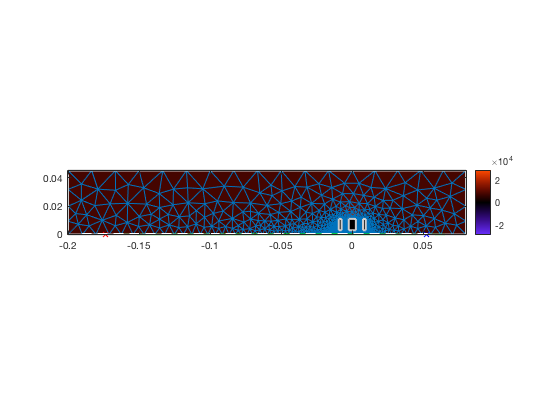




    
    elementary_charge   = 1.60217662e-19;
        
    Nt = 1500;


    Nangle = 100;
        
    E_center = 30*1e3*elementary_charge;
    ion_mass = 5.1477e-26;
    v_center = sqrt(2*E_center / ion_mass);
    delta_E = 10*elementary_charge; 
    v_spread = sqrt(2*delta_E / ion_mass);
    
    angle = linspace(-2.5e-3,2.5e-3,Nangle);
    
    
    y_radius = 0;
    velocities = v_center;
    
    x_pos = -173.5e-3;
    
    [xx, yy, angles, vv] = ndgrid(x_pos, y_radius, angle, velocities);
    angles = angles(:);
    vv = vv(:);
    xv0 = [xx(:)'; yy(:)'; zeros(length(xx(:)),1)'; (vv.*cos(angles))'; (vv.*sin(angles))'; zeros(length(xx(:)),1)'];

        x_p = 52.5e-3;
        y_p  = 0;
        z_p  = 0;
        vx_p = 1e-3;
        vy_p = 0;
        vz_p = 0;

        obj_weights = [1, 1, 0, 0, 0, 0];
 
        end_time = (120e-3 ./ (v_center))*2.5;
        end_time = end_time - 0.2*end_time;
        electron_mass       = 1.6605e-27;

        n_charges = -1;
        n_masses = ion_mass/electron_mass;
        

        %clear particles
 
        for zz = 1:size(xv0,2)
            particles(zz) = Particle(xv0(4:6,zz),'Velocity',n_masses,n_charges,xv0(1:3,zz), 0, end_time, Nt);
        end

        hit_objective = @(x_v) hitObjective3D_wrap(...
            x_v, x_p, y_p, z_p, vx_p, vy_p, vz_p, obj_weights);
        xyz = [measBox(1), measBox(3); measBox(2),measBox(4); -2,0];
        Nxy = [measNxy(1), measNxy(2), 2];
        VV = cylindricalVelocity_Verlet(xyz,Nxy, particles, hit_objective, u_cartesian);
        VV = VV.calculateF_dF;

        figure(100); clf

        imagesc_centered(xCoarse, yCoarse, u'); axis xy image; colorbar
        ax = axis;
        colormap orangecrush
        hold on
        femProblem.poi.tnMesh.plotMesh();

        geometry = fem.instantiatedGeom.geometry;
        plot([geometry.vertices(geometry.lines(:,1),1), geometry.vertices(geometry.lines(:,2),1)]', ...
            [geometry.vertices(geometry.lines(:,1),2), geometry.vertices(geometry.lines(:,2),2)]', 'color', [0.8 0.8 0.8], 'linewidth', 2)


        for ii = 1:size(xv0,2)
            plot(VV.ParticleArray(ii).xx, VV.ParticleArray(ii).yy,'g', 'LineWidth', 1)
            plot(VV.ParticleArray(ii).xx(1), VV.ParticleArray(ii).yy(1),'rx')
        end
        plot(x_p,y_p,'bx')



        plot(measBox([1,3,3,1,1]), measBox([2,2,4,4,2]), 'w--');
        axis(ax)

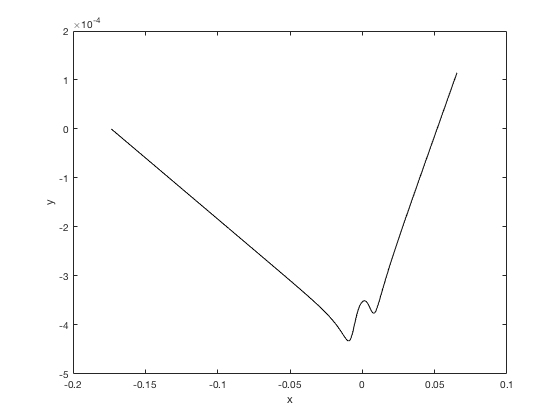

        
        figure(110)
        clf
        plot(VV.ParticleArray(1).xx, VV.ParticleArray(1).yy,'k','LineWidth',1)
        xlabel('x')
        ylabel('y')  

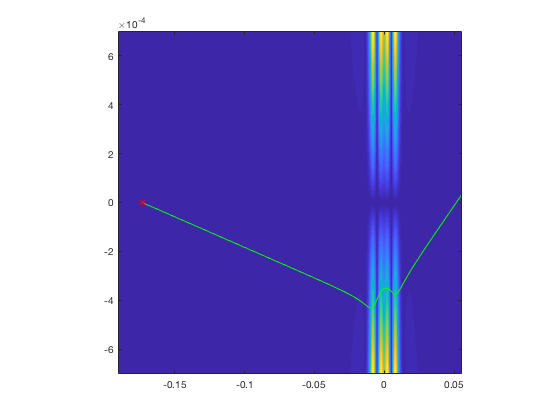

        
        figure(111+1)
        clf
        imagesc(VV.x_grid,VV.r_grid,abs(VV.Er(:,:,2))')
        axis xy
        axis square
        hold on 
        plot(VV.ParticleArray(1).xx, VV.ParticleArray(1).yy,'g', 'LineWidth', 1)
        plot(VV.ParticleArray(1).xx(1),VV.ParticleArray(1).yy(1),'rx')

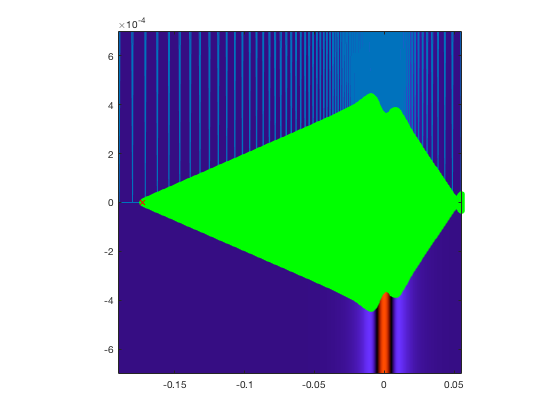

        
        figure(1510+1)
        clf
        imagesc(VV.x_grid,VV.r_grid,VV.V(:,:,2)')
        axis xy
        axis square
        hold on 
        femProblem.poi.tnMesh.plotMesh();

        for ii = 1:size(xv0,2)
            plot(VV.ParticleArray(ii).xx, VV.ParticleArray(ii).yy,'o','Color','g', 'LineWidth', 1)
            plot(VV.ParticleArray(ii).xx(1), VV.ParticleArray(ii).yy(1),'rx')
        end
        colormap orangecrush

        %end